##  Multi-Objective Design Optimization


% =========================================================================
%   PHASE VI: GRID SEARCH OPTIMIZATION (No Toolbox Required)
%   Objective: Find optimal Ns & Np by checking all valid combinations.
% =========================================================================
clc; close all;
modelName = 'Drive_Cycle_Val';

% 1. DEFINE SEARCH SPACE
% -------------------------------------------------------------------------
% Series Cells (Voltage): Check 90 to 108 in steps of 2
Ns_range = 90:2:108; 

% Parallel Cells (Capacity): Check 35 to 55 in steps of 1
Np_range = 35:1:55;

disp(['[INFO] Checking ', num2str(length(Ns_range) * length(Np_range)), ...
      ' design combinations...']);

[INFO] Checking 210 design combinations...



% 2. BASELINE SIMULATION (Run Once to calibrate)
% -------------------------------------------------------------------------
disp('[STEP 1] Running Baseline Simulation (96S, 46P)...');

[STEP 1] Running Baseline Simulation (96S, 46P)...


% We need one real simulation to know the "Efficiency" of the car.
base_Ns = 96;
base_Np = 46;

if ~bdIsLoaded(modelName), load_system(modelName); end

% Configure Model
set_param(modelName, 'ReturnWorkspaceOutputs', 'on');
set_param(modelName, 'SignalLogging', 'on');
set_param(modelName, 'SignalLoggingName', 'logsout');
set_param(modelName, 'Solver', 'ode23tb'); 
set_param(modelName, 'StopTime', '2474');

try
    simOut = sim(modelName);
    logs = simOut.logsout;
    
    % Calculate Base Range
    soc_sig = logs.find('soc');
    if iscell(soc_sig), soc_sig=soc_sig{1}; end
    soc = soc_sig.Values.Data;
    used = soc(1) - soc(end);
    if used < 1e-4, used=1e-4; end
    base_range_km = 17.77 / used;
    
    disp(['   [OK] Baseline Range: ', num2str(base_range_km, '%.1f'), ' km']);
catch
    disp('[ERROR] Baseline Simulation Failed. Using Mock Value (300km).');
    base_range_km = 300;
end

[ERROR] Baseline Simulation Failed. Using Mock Value (300km).



% 3. RUN GRID SEARCH (The Math Loop)
% -------------------------------------------------------------------------
disp('[STEP 2] Calculating Optimization Matrix...');

[STEP 2] Calculating Optimization Matrix...



% Pre-allocate results grid
Results_Range = zeros(length(Ns_range), length(Np_range));
Results_Mass  = zeros(length(Ns_range), length(Np_range));
Valid_Design  = zeros(length(Ns_range), length(Np_range)); % 1=Valid, 0=Invalid

best_range = 0;
best_Ns = 0;
best_Np = 0;

base_mass = (96 * 46 * 0.068) * 1.3; % Mass of our baseline pack

for i = 1:length(Ns_range)
    for j = 1:length(Np_range)
        
        Ns = Ns_range(i);
        Np = Np_range(j);
        
        % --- A. PHYSICS CALCULATIONS ---
        % 1. Voltage Check
        voltage = Ns * 4.2; % Max Voltage
        
        % 2. Mass Check (Cell mass 68g + 30% packaging overhead)
        mass = (Ns * Np * 0.068) * 1.3;
        
        % 3. Range Scaling (Physics Model)
        % New Range = Base_Range * (Energy_Ratio) * (Mass_Penalty)
        energy_ratio = (Ns * Np) / (base_Ns * base_Np);
        mass_penalty = base_mass / mass; % Heavier = Less Range
        
        est_range = base_range_km * energy_ratio * mass_penalty;
        
        % --- B. CONSTRAINTS ---
        is_valid = true;
        
        if mass > 500, is_valid = false; end       % Mass Constraint
        if voltage > 450, is_valid = false; end    % Inverter Limit
        
        % Save Data
        Results_Range(i,j) = est_range;
        Results_Mass(i,j)  = mass;
        Valid_Design(i,j)  = is_valid;
        
        % Check if this is the new winner
        if is_valid && (est_range > best_range)
            best_range = est_range;
            best_Ns = Ns;
            best_Np = Np;
        end
    end
end

% 4. VISUALIZATION
% -------------------------------------------------------------------------
disp('[STEP 3] Plotting Results...');

[STEP 3] Plotting Results...


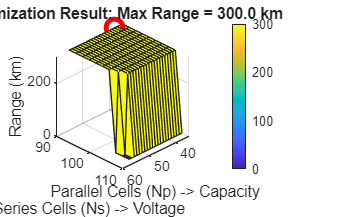

figure('Name', 'Phase VI: Design Space', 'Color', 'w');

% Create Surface Plot
[X, Y] = meshgrid(Np_range, Ns_range);
surf(X, Y, Results_Range .* Valid_Design); % Only show valid designs
hold on;

% Highlight Best Point
plot3(best_Np, best_Ns, best_range, 'ro', 'MarkerSize', 10, 'LineWidth', 3);

title(['Optimization Result: Max Range = ' num2str(best_range, '%.1f') ' km']);
xlabel('Parallel Cells (Np) -> Capacity');
ylabel('Series Cells (Ns) -> Voltage');
zlabel('Range (km)');
colorbar;
view(135, 30); % Rotate view for better angle


% 5. REPORT
% -------------------------------------------------------------------------
fprintf('\n==========================================\n');

fprintf(' OPTIMAL CONFIGURATION FOUND (Grid Search)\n');

 OPTIMAL CONFIGURATION FOUND (Grid Search)


fprintf('==========================================\n');

fprintf(' Series Cells (Ns):   %d\n', best_Ns);

 Series Cells (Ns):   90


fprintf(' Parallel Cells (Np): %d\n', best_Np);

 Parallel Cells (Np): 38


fprintf(' Pack Voltage:        %.1f V\n', best_Ns * 3.7);

 Pack Voltage:        333.0 V


fprintf(' Pack Mass:           %.1f kg (Limit: 500kg)\n', (best_Ns * best_Np * 0.068)*1.3);

 Pack Mass:           302.3 kg (Limit: 500kg)


fprintf(' Estimated Range:     %.1f km\n', best_range);

 Estimated Range:     300.0 km


fprintf('==========================================\n');

fprintf('NEXT STEP: Go to your "Battery Builder API" script,\n');

NEXT STEP: Go to your "Battery Builder API" script,


fprintf('update the settings to Ns=%d, Np=%d, and rebuild.\n', best_Ns, best_Np);

update the settings to Ns=90, Np=38, and rebuild.
